clc;
clear all;
close all;
x=input('inter the sequence for DIT FFT');
N=input('number of points ');
n=length(x);
x=[x zeros(1,N-n)];
M=log2(N);
X=bitrevorder(x);
for a=1:M
    b=2^a;
    for c=1:b:N-b+1
        for d=0:(b/2)-1
            W=exp(-1*1i*2*pi*d/b);
            xeven=X(c+d);
            xodd=X(c+d+(b/2));
            X(c+d)=xeven+W*xodd;
            X(c+d+b/2)=xeven-W*xodd;
        end
    end
end
disp(X)

   6.0000 + 0.0000i  -2.0000 + 2.0000i  -2.0000 + 0.0000i  -2.0000 - 2.0000i



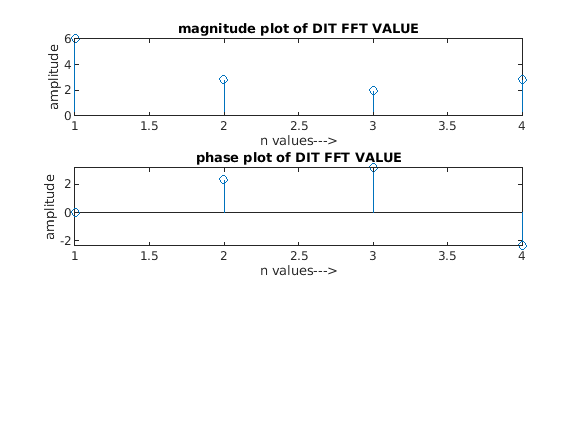

magnitude=abs(X);
subplot(3,1,1)
stem(magnitude);
xlabel('n values--->');
ylabel('amplitude');
title('magnitude plot of DIT FFT VALUE');
phase=angle(X);
subplot(3,1,2)
stem(phase);
xlabel('n values--->');
ylabel('amplitude');
title('phase plot of DIT FFT VALUE');